# Parameters

This file list the parameters used to evaluate the performance of the SIM. The parameters follows those listed in [1, Sec. VI]

## Simulation parameters

total_iteration=10^3;%referred to the number of transmitted packets, see [1, Sec. VI.D]
%fixing parameters
total_iteration=1

## Scenario parameters

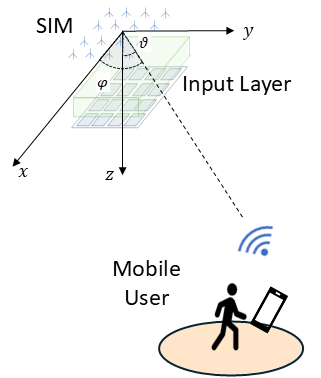

Fig. 1: Scenario

x_max=5;%maximum mobility area in the ground plane
y_max=5;%maximum mobility area in the ground plane
z_max=2.5;%height of the room
pos_SIM = [x_max/2 y_max/2 2.5]; % SIM position in meters
pos_MU = [2 4 1.5]; % MU position in meters
pos_MU_max=[x_max y_max 0];%max position of the MU in the positive ground plane
d_MU_SIM_max=norm(pos_SIM-pos_MU);%maximum distance from the MU to the SIM
theta_max=atan2(norm(pos_MU_max),d_MU_SIM_max)+pi;%maximum angle between the MU and SIM
theta_min=atan2(-norm(pos_MU_max),d_MU_SIM_max)+pi;%maximum angle between the MU and SIM

## **802.11ad parameters**

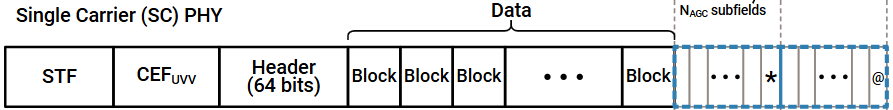

Fig 1: DMG Format PPDU for a single carrrier [2].

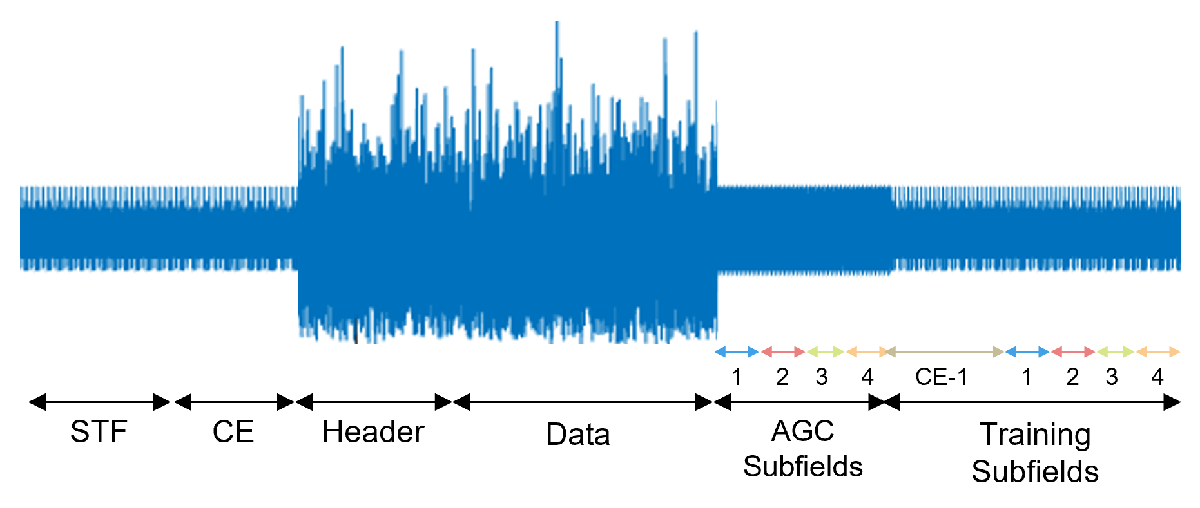

Fig 2: Time-domain DMG Format PPDU for a single carrrier [4].


% Create a configuration object for 802.11
cfgDMG_loc = wlanDMGConfig;
fc=28*10^9;%transmission frequency
lambda=physconst('LightSpeed')/fc;
% SNR_dB=[2 4 6 8 10];
idleTime=20e-6;% Idle time between packets [6]

fs = wlanSampleRate(cfgDMG_loc);%sampling time of the receiver node [6]
BW = 2640*10^6;%bandwidth, see [6]
% BW = 200*10^6;
%Configuring the transmitted waveform for localization applications
%modulation format [3]
cfgDMG_loc.MCS="1"; % Single-carrier modulation
%packet format
%cfgDMG_loc.TrainingLength = 4;   % Use 4 training subfields (TRN) [3]
%cfgDMG_loc.PacketType = 'TRN-T'; % Transmitter training
cfgDMG_loc.PSDULength = 1; % PSDULength in bytes
ind_loc=wlanFieldIndices(cfgDMG_loc);
T_PPDU_loc=(double(ind_loc.DMGData(2))/fs)+idleTime;
disp(['Wireless packet type: ',phyType(cfgDMG_loc)])

Wireless packet type: SC



waveform_k= 2*pi/lambda;

#### SIM paramaters

%N=16; %see [1, Sec. VI.C.]
N_x=[2 3 4 5 6 7 8 9 10 11 12 13 14 15];%[4 5 6 7 8 9];%SIM dimension of the zero Layer
N_x=12;
N_y=N_x; %to account for a balanced error in the x an y axes
N=N_x.*N_y;
d_x=lambda/2;
%SIM Position
%defining the hall dimensions in accordance with Table 7.2-4 pp. 21 in [8]
L_hall= 10; % length of factory hall
W_hall=5; %width of hall
H_hall=5; %height (ceiling)
SIM_Pos = [L_hall/2 W_hall/2 H_hall];       % SIM center on ceiling
simSize = 1.0;          % just for plotting SIM frame size (meters)
% Rx_element='38.901';   % good surrogate fkr directional, patch-like element; Peak gain ≈ 8 dBi; realistic azimuth / elevation beamwidths (not a sphere).
% Rx_array_normal='z';
Rx_orientation=[0; 0; 0];% [azimuth; downtilt; slant], % boresight -z
rxElem = phased.CosineAntennaElement( ...
    'FrequencyRange', [fc-5e9 fc+5e9], ...
    'CosinePower',    [2 2]);  % ~65° HPBW in az/el
rxArray = phased.URA( ...
    'Size',           [N_y N_x], ...
    'Element',        rxElem, ...
    'ElementSpacing', [lambda/2 lambda/2]);  % 0.5 λ spacing

Grx_dBi = 8;                          % desired antenna peak gain
Grx = 10^(Grx_dBi/20);                  % convert to amplitude factor

%number of meta-atoms in the x and y direction
M_x=sqrt(225); %as follows from [1, Sec. IV A] for the (4x4 grid)
M_y=M_x;
%number of intermediate SIM layers
L=13; %as follows from [1, Sec. IV A] for the (4x4 grid)

#### Mobile User parameters

total_MUpositions=1;
h_MU=1;
MU_speed=1;%meter per second
Ptx_dBm = 10; % transmit power in dBm
Ptx = db2pow(Ptx_dBm-30);
Gtx_elem_dBi = 8;                          % desired antenna peak gain
                 % convert to amplitude factor
Gtx_array_dB = 6;     % 4-element array gain
Gtx_dBi   = Gtx_elem_dBi + Gtx_array_dB;   % ≈14 dBi
Gtx = 10^(Gtx_dBi/20); 

Antenna: Configure the transmit array size as a vector of the form [*M* *N* *P* *M*g *N*g], which specifies a rectangular panel of dimension (*M*g *N*g) of an antenna array of dimension (*M*  *N*) and number of polarizations (*P*). The total number of polarized elements in the array is *M*×*N*×*P*×*M*g×*N*g.

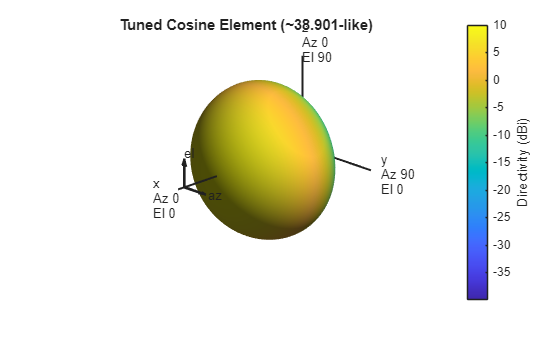

% tx_Antenna_Size = [1 4 1 1 1]; %as follows from the mmWave Antenna chip from [7], except for the number of polarizations
% Tx_element='38.901';   % good surrogate fkr directional, patch-like element; Peak gain ≈ 8 dBi; realistic azimuth / elevation beamwidths (not a sphere).
Tx_array_normal='z';
Tx_orientation=[0; 0; 0];% [azimuth; downtilt; slant], % boresight +z

% Define a valid phased-array element (pick one):
txElem  = phased.CosineAntennaElement('FrequencyRange',[fc-5e9 fc+5e9], ...
                                 'CosinePower',[2 2]);
% figure; pattern(txElem, fc);
% title('Tuned Cosine Element (~38.901-like)');


% Build URA in x–y plane, boresight +z
txArray = phased.ULA('NumElements',4,'Element',txElem,'ElementSpacing',lambda/2);


#### Localization protocol parameters

T_coh=sqrt(9/16*pi)*physconst('LightSpeed')*MU_speed/fc
%T=1024;%see [1, Sec. VI.C.]
%T_x=ceil(sqrt(T_coh/T_loc))
T_x=1:ceil(sqrt(T_coh/T_PPDU_loc));
T_y=T_x; %accounting for a balanced error in the x an y axes of the Fourier transform
T=T_x.*T_y
%Fixing parameters
T_x=12;
T_y=T_x; %accounting for a balanced error in the x an y axes of the Fourier transform
T=T_x.*T_y



#### Channel

maxDoppler = (MU_speed/physconst('LightSpeed'))*fc;
%Evaluating the delay spread according to Table 7.5-6 Table 7.5-6 Part-3: Channel model parameters for InF in page 48
V_hall= L_hall*W_hall*H_hall;%hall volume (m³)
S_hall= 2*(L_hall*H_hall+W_hall*H_hall)+2*(L_hall*W_hall); %total surface of 4 walls + floor + ceiling (m²)
%LOS
u_lgDS=log10(26*V_hall/S_hall+14)-9.35;%mean
sigma_lgDS=0.15;%variance
%NLOS
% u_lgDS=log10(30*V/S+32)-9.44;%mean
% sigma_lgDS=0.19;%variance
%Evaluating the wanted delay spread, as follows from Eq. (7.7-1) in page 79
DS_ns = 10^(u_lgDS+sigma_lgDS);
%Delay profile
% CDL-A → NLOS, low delay spread, small angular spreads
% CDL-B → NLOS, slightly larger angular spreads
% CDL-C → rich NLOS scattering, larger delay spread
% CDL-D → LOS model (moderate K-factor)
% CDL-E → strong LOS (larger first-tap power)
profile   = 'CDL-D';      % NLOS: 'CDL-A/B/C'; LOS: 'CDL-D/E'

%% --- CDL channel object (TR 38.901) --------------------------------------
cdl = nrCDLChannel;
cdl.DelayProfile         = profile;          % NLOS: CDL-A/B/C, LOS: CDL-D/E LOS (§7.7.1)
cdl.DelaySpread          = DS_ns*1e-9;       % set RMS-DS via scaling (Eq. 7.7-1 in §7.7.3)
cdl.CarrierFrequency     = fc;
cdl.SampleRate           = fs;
cdl.MaximumDopplerShift  = maxDoppler;

% Attach the antenna elements to the CDL
cdl.TransmitAntennaArray = txArray;
cdl.ReceiveAntennaArray = rxArray;

% Orient the transmit and receive antenna arrays to point at each other by using the LOS path angles returned in the characteristic information.
cdlInfo = cdl.info;
cdl.TransmitArrayOrientation = [cdlInfo.AnglesAoD(1) cdlInfo.AnglesZoD(1)-90 0]';
cdl.ReceiveArrayOrientation = [cdlInfo.AnglesAoA(1) cdlInfo.AnglesZoA(1)-90 0]';

% figure; displayChannel(cdl,'LinkEnd','Tx');
% view(0,90)
% figure; displayChannel(cdl,'LinkEnd','Rx'); title('SIM Rx array');
% view(0,90)

#### Noise parameters; see [3]

% Noise and interference parameters
noiseFigure = 7;                             % dB
thermalNoiseDensity = -174;                  % dBm/Hz
rxInterfDensity = -165.7;                    % dBm/Hz

% Calculate the corresponding noise power
totalNoiseDensity = 10*log10(10^((noiseFigure+thermalNoiseDensity)/10)+10^(rxInterfDensity/10));
var_noise_dB = totalNoiseDensity-30+10*log10(BW); % dB
var_noise=db2pow(var_noise_dB);


#### SNR evaluation

%Free path loss in the direct link IRS-MU
Lr = (lambda/(2*pi*norm(d_MU_SIM_max)))^2;
SNR_dB=Ptx_dBm-30+pow2db(Lr)-var_noise_dB

SNR_dB = 28.2642

#### Plotting parameters

font=15;

## References

[1] J. An et al., "Two-Dimensional Direction-of-Arrival Estimation Using Stacked Intelligent Metasurfaces," in IEEE Journal on Selected Areas in Communications, vol. 42, no. 10, pp. 2786-2802, Oct. 2024. DOI [10.1109/JSAC.2024.3414613](https://doi.org/10.1109/JSAC.2024.3414613)

[2] WLAN PPDU Structure, [https://de.mathworks.com/help/wlan/gs/dmg-ppdu-structure.html](https://de.mathworks.com/help/wlan/gs/dmg-ppdu-structure.html)

[3] Model Reconfigurable Intelligent Surfaces with CDL Channels [https://ch.mathworks.com/help/5g/ug/model-reconfigurable-intelligent-surfaces-with-cdl-channels.html](https://ch.mathworks.com/help/5g/ug/model-reconfigurable-intelligent-surfaces-with-cdl-channels.html)

[4] [https://ch.mathworks.com/help/wlan/ug/802-11ad-waveform-generation-with-beamforming.html](https://ch.mathworks.com/help/wlan/ug/802-11ad-waveform-generation-with-beamforming.html)

[5] [https://ch.mathworks.com/help/phased/ug/signal-collection.html](https://ch.mathworks.com/help/phased/ug/signal-collection.html)

[6] [https://ch.mathworks.com/help/wlan/ref/wlanwaveformgenerator.html#bvdi39e-4](https://ch.mathworks.com/help/wlan/ref/wlanwaveformgenerator.html#bvdi39e-4)

[7] J. Oh, K. Kim, J. Choi, and J. Oh, "Tightly Embedded Modular Antenna-in-Display (MAiD) Into the Panel Edge of Display With Dual-Polarization for 5G Smartphones," IEEE Transactions on Antennas and Propagation, vol. 73, no. 2, pp. 1209–1214, Feb. 2025, doi: 10.1109/TAP.2024.3501415.

[8] "Study on channel model for frequencies from 0.5 to 100 GHz (Release 16)," 3GPP, TR 38.901 V16.1.0, Nov. 2020.  